%% AE571 Final Project: Complete Analysis (Standard + Extra Credit)
% Author: Team 2
% Date: December 2025
% Description: 
%   Full Fuel-Air Cycle Analysis for Gasoline and Isooctane.
%   Features:
%   - Variable Specific Heat (NASA Polynomials)
%   - Exact Energy Balance (fzero) for Cycle Temperatures
%   - LHV Calculated at T2 and used as Qin
%   - Propeller Optimization & Fuel Flow Integration

clear; clc; close all; format short g;

%% --- SECTION 1: GLOBAL SETUP ---
% Define all constants, engine parameters, and chemical data needed for the analysis.

% 1.1 Constants
rho_air = 1.22;         % Air density at sea level (kg/m^3)
T1 = 298;               % Ambient Temp (K)
P1 = 100;               % Ambient Pressure (kPa)
rc = 16;                % Compression Ratio
n1 = 1.38;              % Polytropic index (compression)
n2 = 1.25;              % Polytropic index (expansion)
sigma = 0.7;            % Round-off coefficient for real cycle work
P_max_limit = 5500;     % Max allowed pressure (kPa)
Ru = 8.314;             % Universal Gas Constant (kJ/kmol*K)

% 1.2 Propeller Constants
D_prop = 3; R_prop = D_prop/2;
n_rpm = 1300; n_rps = n_rpm / 60;
B_blades = 3; chord = 0.1;

% 1.3 Vectors
phi_vec = [0.6, 0.8, 1.0];      % Equivalence ratios to test
V_kmh = 116:2:702;              % Velocity range (km/h)
V_ms = V_kmh ./ 3.6;            % Velocity range (m/s)
J_vec = V_ms ./ (n_rps * D_prop); % Advance Ratio J

% 1.4 COEFFICIENTS
global coeffs
% Fuels (Heywood Format) - Used for Enthalpy of Fuel
coeffs.gasoline = [-24.078, 256.63, -201.68, 64.750, 0.5808, -27.562];
coeffs.isooctane = [-0.55313, 181.62, -97.787, 20.402, -0.03095, -60.751];

% Species (NASA Format) - Low Temp (< 1000K)
coeffs.O2_lo   = [0.03212936E+2, 0.11274864E-2, -0.05756150E-5, 0.13138773E-8, -0.08768554E-11, -0.10052490E+4];
coeffs.N2_lo   = [0.03298677E+2, 0.14082404E-2, -0.03963222E-4, 0.05641515E-7, -0.02444854E-10, -0.10208999E+4];
coeffs.CO2_lo  = [0.02275724E+2, 0.09922072E-1, -0.10409113E-4, 0.06866686E-7, -0.02117280E-10, -0.04837314E+6];
coeffs.H2O_lo  = [0.03386842E+2, 0.03474982E-1, -0.06354696E-4, 0.06968581E-7, -0.02506588E-10, -0.03020811E+6];

% Species (NASA Format) - High Temp (> 1000K)
coeffs.O2_hi   = [0.03697578E+2, 0.06135197E-2, -0.12588420E-6, 0.01775281E-9, -0.11364354E-14, -0.12339301E+4];
coeffs.N2_hi   = [0.02926640E+2, 0.14879768E-2, -0.05684760E-5, 0.10097038E-9, -0.06753351E-13, -0.09227977E+4];
coeffs.CO2_hi  = [0.04453623E+2, 0.03140168E-1, -0.12784105E-5, 0.02393996E-8, -0.16690333E-13, -0.04896696E+6];
coeffs.H2O_hi  = [0.02672145E+2, 0.03056293E-1, -0.08730260E-5, 0.12009964E-9, -0.06391618E-13, -0.02989921E+6];

%% --- SECTION 2: PROPELLER ANALYSIS ---
% Calculates the best pitch angle for every flight velocity using Blade Element Theory.

fprintf('========================================\n');

fprintf('   TASK 4: PROPELLER OPTIMIZATION\n');

   TASK 4: PROPELLER OPTIMIZATION


fprintf('========================================\n');

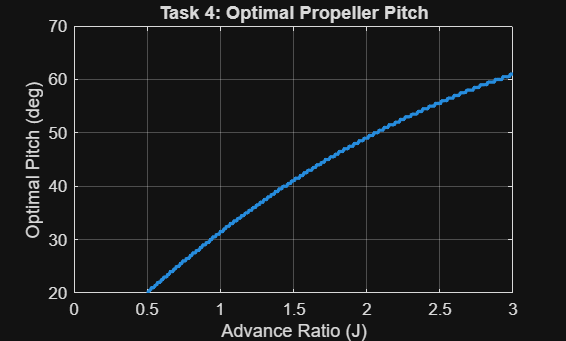


% Range of pitch angles to test
beta_pitch_vec = 15:0.5:75; 
best_beta_vec = zeros(size(J_vec));
Cp_required_vec = zeros(size(J_vec));

% Loop through every velocity (Advance Ratio J)
for i = 1:length(J_vec)
    J = J_vec(i); V = V_ms(i);
    max_eta_p = 0; best_beta = 0; best_Cp = 0;
    
    % Test every pitch angle to find the one with max efficiency
    for b_idx = 1:length(beta_pitch_vec)
        beta_deg = beta_pitch_vec(b_idx);
        
        % Integrate forces along the blade radius
        r_vec = linspace(0.15*R_prop, R_prop, 60); 
        p_geom = 2 * pi * (0.75*R_prop) * tan(deg2rad(beta_deg));
        beta_r = atan(p_geom ./ (2*pi*r_vec));
        phi_flow = atan(V ./ (2*pi*n_rps.*r_vec));
        alpha_rad = beta_r - phi_flow;
        
        % Lift and Drag coefficients
        CL = 6.2 * alpha_rad; 
        CD = 0.008 - 0.003*CL + 0.01*(CL.^2);
        
        % Elemental forces
        V_rel_sq = (V ./ sin(phi_flow)).^2;
        dFT = 0.5 * rho_air * V_rel_sq .* chord .* (CL.*cos(phi_flow) - CD.*sin(phi_flow));
        dQ  = 0.5 * rho_air * V_rel_sq .* chord .* r_vec .* (CL.*sin(phi_flow) + CD.*cos(phi_flow));
        
        % Total Thrust and Torque
        FT = trapz(r_vec, dFT) * B_blades;
        Q  = trapz(r_vec, dQ) * B_blades;
        
        % Non-dimensional coefficients
        CT = FT / (rho_air * n_rps^2 * D_prop^4);
        CQ = Q / (rho_air * n_rps^2 * D_prop^5);
        CP = 2 * pi * CQ;
        
        % Calculate Efficiency
        eta_p = 0; if CP>1e-6, eta_p = (J*CT)/CP; end
        
        % Update best if this pitch is better
        if eta_p > max_eta_p && eta_p < 0.98
            max_eta_p = eta_p; best_beta = beta_deg; best_Cp = CP;
        end
    end
    best_beta_vec(i) = best_beta; Cp_required_vec(i) = best_Cp;
end

% Plot Optimal Pitch vs J
figure(1); plot(J_vec, best_beta_vec, 'LineWidth', 2);
xlabel('Advance Ratio (J)'); ylabel('Optimal Pitch (deg)'); 
grid on; title('Task 4: Optimal Propeller Pitch');


################ Gasoline ################


--- Task 1: LHV at T2 ---


Phi: 0.6 | LHV: 43727.74 kJ/kg
Phi: 0.8 | LHV: 43727.74 kJ/kg
Phi: 1.0 | LHV: 43727.74 kJ/kg


--- Tasks 2 & 3: Cycle Performance ---


Phi   Type       Alpha      Beta       W_cyc(kJ)    Eta_th     MEP(kPa)  


0.6   Dual       1.20       2.23       654.87       0.3772     838.05    
0.8   Dual       1.20       2.61       791.85       0.3466     1023.24   
1.0   Dual       1.20       2.97       909.73       0.3227     1186.87   


>>> DETAILED STATE VARIABLES (Gasoline) <<<



Cycle Phi = 0.6:


   State |      P (kPa) |       T (K) |  v (m^3/kg)


   ----------------------------------------------


     1   |       100.00 |      298.00 |     0.83352
     2   |      4588.66 |      854.64 |     0.05210
     3   |      5500.00 |      994.97 |     0.05210
     4   |      5500.00 |     2216.36 |     0.11605
     5   |       467.74 |     1353.84 |     0.83352



Cycle Phi = 0.8:


   State |      P (kPa) |       T (K) |  v (m^3/kg)


   ----------------------------------------------


     1   |       100.00 |      298.00 |     0.82546
     2   |      4588.66 |      854.64 |     0.05159
     3   |      5500.00 |      985.66 |     0.05159
     4   |      5500.00 |     2573.37 |     0.13469
     5   |       570.40 |     1635.56 |     0.82546



Cycle Phi = 1.0:


   State |      P (kPa) |       T (K) |  v (m^3/kg)


   ----------------------------------------------


     1   |       100.00 |      298.00 |     0.81760
     2   |      4588.66 |      854.64 |     0.05110
     3   |      5500.00 |      976.59 |     0.05110
     4   |      5500.00 |     2901.63 |     0.15183
     5   |       670.46 |     1904.78 |     0.81760


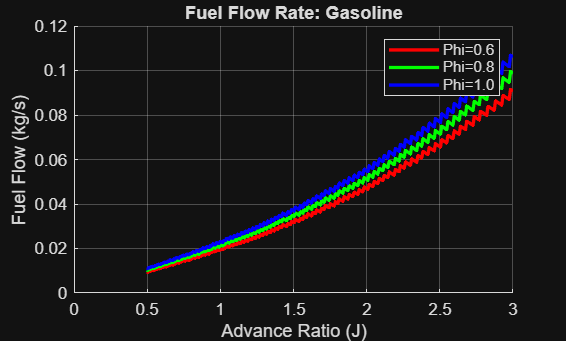


################ Isooctane ################


--- Task 1: LHV at T2 ---


Phi: 0.6 | LHV: 44709.95 kJ/kg
Phi: 0.8 | LHV: 44709.95 kJ/kg
Phi: 1.0 | LHV: 44709.95 kJ/kg


--- Tasks 2 & 3: Cycle Performance ---


Phi   Type       Alpha      Beta       W_cyc(kJ)    Eta_th     MEP(kPa)  


0.6   Dual       1.20       2.22       651.26       0.3793     832.55    
0.8   Dual       1.20       2.60       788.01       0.3486     1016.88   
1.0   Dual       1.20       2.96       905.93       0.3246     1179.90   


>>> DETAILED STATE VARIABLES (Isooctane) <<<



Cycle Phi = 0.6:


   State |      P (kPa) |       T (K) |  v (m^3/kg)


   ----------------------------------------------


     1   |       100.00 |      298.00 |     0.83440
     2   |      4588.66 |      854.64 |     0.05215
     3   |      5500.00 |      989.79 |     0.05215
     4   |      5500.00 |     2193.94 |     0.11559
     5   |       464.85 |     1338.49 |     0.83440



Cycle Phi = 0.8:


   State |      P (kPa) |       T (K) |  v (m^3/kg)


   ----------------------------------------------


     1   |       100.00 |      298.00 |     0.82660
     2   |      4588.66 |      854.64 |     0.05166
     3   |      5500.00 |      978.92 |     0.05166
     4   |      5500.00 |     2542.47 |     0.13418
     5   |       566.70 |     1613.81 |     0.82660



Cycle Phi = 1.0:


   State |      P (kPa) |       T (K) |  v (m^3/kg)


   ----------------------------------------------


     1   |       100.00 |      298.00 |     0.81899
     2   |      4588.66 |      854.64 |     0.05119
     3   |      5500.00 |      968.35 |     0.05119
     4   |      5500.00 |     2861.86 |     0.15128
     5   |       666.01 |     1876.17 |     0.81899


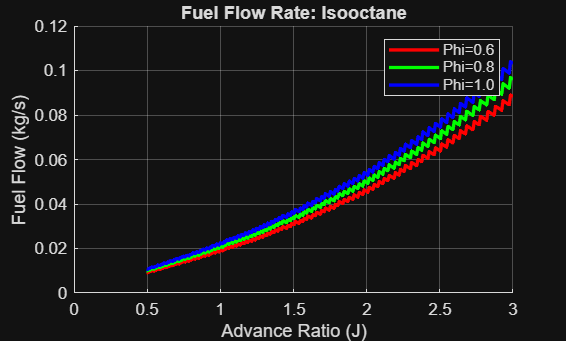


%% --- SECTION 3: MASTER FUEL LOOP ---
% Loops through both fuel types: Gasoline (Standard) and Isooctane (Extra Credit).

fuel_names = {'Gasoline', 'Isooctane'};
fuel_configs(1).x = 8.26; fuel_configs(1).y = 15.5; 
fuel_configs(1).MW = 114.8; fuel_configs(1).c = coeffs.gasoline;

fuel_configs(2).x = 8;    fuel_configs(2).y = 18;   
fuel_configs(2).MW = 114.23; fuel_configs(2).c = coeffs.isooctane;

for f_idx = 1:length(fuel_configs)
    current_fuel = fuel_names{f_idx};
    Fx = fuel_configs(f_idx).x; Fy = fuel_configs(f_idx).y;
    Fmw = fuel_configs(f_idx).MW; Fc = fuel_configs(f_idx).c;
    
    fprintf('\n################ %s ################\n', current_fuel);
    
    % --- TASK 1: LHV at T2 ---
    % Calculates Lower Heating Value at the end-of-compression temperature (T2).
    fprintf('--- Task 1: LHV at T2 ---\n');
    T2 = T1 * (rc)^(n1 - 1);
    LHV_results = zeros(length(phi_vec), 1); 
    
    for i = 1:length(phi_vec)
        phi = phi_vec(i);
        b = Fx; d = Fy / 2; a_stoich = Fx + Fy/4; 
        a = a_stoich / phi; c_exc = a - a_stoich; e = a * 3.76;
        
        % Calculate Enthalpies at T2 using polynomials
        h_f = calc_fuel_h(T2, Fc); 
        h_O2 = calc_nasa_h(T2, coeffs.O2_lo);
        h_N2 = calc_nasa_h(T2, coeffs.N2_lo);
        h_CO2 = calc_nasa_h(T2, coeffs.CO2_lo);
        h_H2O = calc_nasa_h(T2, coeffs.H2O_lo);
        
        H_R = 1*h_f + a*h_O2 + e*h_N2;
        H_P = b*h_CO2 + d*h_H2O + c_exc*h_O2 + e*h_N2;
        
        % LHV = (Enthalpy Reactants - Enthalpy Products) / Molar Mass
        LHV_val = (H_R - H_P) / Fmw; 
        LHV_results(i) = LHV_val;
        fprintf('Phi: %.1f | LHV: %.2f kJ/kg\n', phi, LHV_val);
    end
    fprintf('\n');
    
    % --- TASK 2 & 3: CYCLE ANALYSIS ---
    % Simulates the engine cycle to find Work, Efficiency, and State Variables.
    fprintf('--- Tasks 2 & 3: Cycle Performance ---\n');
    fprintf('%-5s %-10s %-10s %-10s %-12s %-10s %-10s\n', 'Phi', 'Type', 'Alpha', 'Beta', 'W_cyc(kJ)', 'Eta_th', 'MEP(kPa)');
    
    cycle_efficiency = zeros(length(phi_vec), 1); 
    clear States; States(length(phi_vec)) = struct(); 
    options = optimset('Display', 'off'); 
    
    for i = 1:length(phi_vec)
        phi = phi_vec(i);
        LHV = LHV_results(i);
        
        % Calculate mixture properties (mass, moles)
        b = Fx; d = Fy/2; a_stoich = Fx + Fy/4; 
        a = a_stoich / phi; c_exc = a - a_stoich; e = a * 3.76;
        n_reac = 1 + a + e; n_prod = b + d + c_exc + e;
        
        MW_mix = (1*Fmw + a*32 + e*28) / n_reac;
        R_mix = Ru / MW_mix;
        mass_mix_kg = n_reac * MW_mix; 
        
        % State 1-2 (Compression)
        v1_spec = (R_mix * T1) / P1;       
        V1 = v1_spec * mass_mix_kg;        
        V2 = V1 / rc;                      
        P2 = P1 * (rc)^n1;
        
        % Heat Input determined by LHV
        Q_in_total = Fmw * LHV; 
        
        % --- COMBUSTION LOGIC ---
        % Calculate Baseline Energy of Products at T2
        U_prod_T2_base = b*calc_nasa_u_smart(T2, coeffs.CO2_lo, coeffs.CO2_hi) + ...
                         d*calc_nasa_u_smart(T2, coeffs.H2O_lo, coeffs.H2O_hi) + ...
                         c_exc*calc_nasa_u_smart(T2, coeffs.O2_lo, coeffs.O2_hi) + ...
                         e*calc_nasa_u_smart(T2, coeffs.N2_lo, coeffs.N2_hi);
        
        % Add Heat Input to find Target Energy
        Target_U3 = U_prod_T2_base + Q_in_total;
        
        % Define energy function to solve for T3
        U_prod_func = @(T) (b*calc_nasa_u_smart(T, coeffs.CO2_lo, coeffs.CO2_hi) + ...
                            d*calc_nasa_u_smart(T, coeffs.H2O_lo, coeffs.H2O_hi) + ...
                            c_exc*calc_nasa_u_smart(T, coeffs.O2_lo, coeffs.O2_hi) + ...
                            e*calc_nasa_u_smart(T, coeffs.N2_lo, coeffs.N2_hi));
        
        % Find theoretical Otto temperature
        try
            T3_otto = fzero(@(T) U_prod_func(T) - Target_U3, [1000, 6000], options);
        catch
            T3_otto = 4000; 
        end
        P3_otto = P2 * (n_prod / n_reac) * (T3_otto / T2);
        
        % Check if pressure exceeds limit -> Switch to Dual Cycle
        if P3_otto <= P_max_limit
            cycle_type = 'Otto';
            P3 = P3_otto; T3 = T3_otto;
            alpha = P3 / P2; beta = 1;
            T4 = T3; P4 = P3; V3 = V2; V4 = V3;
        else
            cycle_type = 'Dual';
            P3 = P_max_limit;
            alpha = P3 / P2;
            V3 = V2;
            
            % Solve for limited T3
            T3 = T2 * (P3/P2) * (n_reac/n_prod);
            
            % Split heat between Const Vol and Const Pressure
            U_prod_T3 = U_prod_func(T3);
            Q_vol = U_prod_T3 - U_prod_T2_base;
            Q_pres = Q_in_total - Q_vol;
            
            % Solve for T4 (Isobaric heat addition uses Enthalpy)
            H_prod_func = @(T) U_prod_func(T) + n_prod * Ru * T;
            H_prod_T3 = H_prod_func(T3);
            Target_H4 = H_prod_T3 + Q_pres;
            
            try
                T4 = fzero(@(T) H_prod_func(T) - Target_H4, [T3, 6000], options);
            catch
                T4 = T3;
            end
            beta = T4 / T3;
            P4 = P3; V4 = V3 * beta;
        end
        
        % State 5 (Expansion)
        delta = V1 / V4; 
        T5 = T4 * (1/delta)^(n2 - 1);
        P5 = P4 * (1/delta)^n2;
        V5 = V1;
        
        % Calculate Work, Efficiency, MEP
        W12 = (P2*V2 - P1*V1) / (1 - n1);   
        W34 = P3 * (V4 - V3);               
        W45 = (P5*V5 - P4*V4) / (1 - n2);   
        W_cycle = sigma * (W12 + W34 + W45);
        
        eta_th = W_cycle / Q_in_total;
        cycle_efficiency(i) = eta_th;
        mep = W_cycle / (V1 - V2);
        
        % Save State Variables
        States(i).phi = phi;
        States(i).P = [P1, P2, P3, P4, P5];
        States(i).T = [T1, T2, T3, T4, T5];
        States(i).v = [V1, V2, V3, V4, V5] ./ mass_mix_kg; 
        
        fprintf('%-5.1f %-10s %-10.2f %-10.2f %-12.2f %-10.4f %-10.2f\n', ...
            phi, cycle_type, alpha, beta, W_cycle/mass_mix_kg, eta_th, mep);
    end
    fprintf('\n');
    
    % Print Detailed State Tables
    fprintf('>>> DETAILED STATE VARIABLES (%s) <<<\n', current_fuel);
    for i = 1:length(phi_vec)
        fprintf('\nCycle Phi = %.1f:\n', States(i).phi);
        fprintf('   State |      P (kPa) |       T (K) |  v (m^3/kg)\n');
        fprintf('   ----------------------------------------------\n');
        for k = 1:5
            fprintf('     %d   | %12.2f | %11.2f | %11.5f\n', k, States(i).P(k), States(i).T(k), States(i).v(k));
        end
    end
    
    %% --- TASK 5: PLOT ---
    % Plots the fuel mass flow rate vs Advance Ratio for this fuel.
    figure(1+f_idx); hold on; 
    colors = {'r', 'g', 'b'};
    for i = 1:length(phi_vec)
        eta = cycle_efficiency(i); LHV = LHV_results(i);
        mdot = zeros(size(J_vec));
        for j = 1:length(J_vec)
            Cp = Cp_required_vec(j);
            P_prop = Cp * rho_air * (n_rps^3) * (D_prop^5); 
            P_brake = P_prop / 0.80; 
            Q_dot = (P_brake / 1000) / eta; 
            mdot(j) = Q_dot / LHV;
        end
        plot(J_vec, mdot, 'LineWidth', 2, 'Color', colors{i}, 'DisplayName', sprintf('Phi=%.1f', phi_vec(i)));
    end
    xlabel('Advance Ratio (J)'); ylabel('Fuel Flow (kg/s)'); legend; grid on;
    title(['Fuel Flow Rate: ' current_fuel]);
end


fprintf('\nAnalysis Complete. Figures Generated.\n');


Analysis Complete. Figures Generated.



%% --- HELPER FUNCTIONS ---

% Calculate Molar Enthalpy of Fuel using Heywood coefficients
function h = calc_fuel_h(T, a)
    t = T/1000;
    h = 4184 * (a(1)*t + a(2)*(t^2)/2 + a(3)*(t^3)/3 + a(4)*(t^4)/4 - a(5)*(t^-1) + a(6));
end

% Calculate Internal Energy of Fuel (u = h - RT)
function u = calc_fuel_u(T, a)
    Ru = 8.314;
    u = calc_fuel_h(T, a) - Ru*T;
end

% Calculate Molar Enthalpy of Species using NASA coefficients
function h = calc_nasa_h(T, a)
    Ru = 8.314;
    h = Ru * T * (a(1) + a(2)*(T)/2 + a(3)*(T^2)/3 + a(4)*(T^3)/4 + a(5)*(T^4)/5 + a(6)/T);
end

% Calculate Internal Energy of Species (u = h - RT)
function u = calc_nasa_u(T, a)
    Ru = 8.314;
    u = calc_nasa_h(T, a) - Ru*T;
end

% Smart Wrapper: Selects correct coeffs for U based on temperature
function u = calc_nasa_u_smart(T, c_lo, c_hi)
    if T < 1000
        u = calc_nasa_u(T, c_lo);
    else
        u = calc_nasa_u(T, c_hi);
    end
end

% Smart Wrapper: Selects correct coeffs for H based on temperature
function h = calc_nasa_h_smart(T, c_lo, c_hi)
    if T < 1000
        h = calc_nasa_h(T, c_lo);
    else
        h = calc_nasa_h(T, c_hi);
    end
end